# Animation

[Open Live Script](matlab:edit physvis_toolbox_animation.mlx)

This tutorial shows how to create animations with PHYSVIS using the `rate` function within a loop.

Consider a particle in a harmonic oscillator potential. Its equations of motion are


$$\begin{array}{l}
\frac{\mathrm{d}}{\mathrm{d}t}r=v,\\
\frac{\mathrm{d}}{\mathrm{d}t}v={-\text{ }\omega }^2 \text{ }r\text{ },
\end{array}$$


where $r$ is its vector position measured from the center of the potential, $v$ is its vector velocity, and $\omega$ is its natural frequency. The discrete form of the equations of motion are


$$\begin{array}{l}
r\left(t+\mathrm{dt}\right)=r\left(t\right)+v\left(t\right)\text{ }\mathrm{dt},\\
v\left(t+\mathrm{dt}\right)=v\left(t\right)-\omega {\text{ }}^2 \text{ }r\left(t+\mathrm{dt}\right)\text{ }\mathrm{dt}\ldotp 
\end{array}$$


Represent this system as a `physvis.Sphere` object and add the physical properties `Velocity` and `Omega.`

particle = physvis.Sphere();
particle.UserData.Omega = 2*pi; % rad/s
particle.UserData.Velocity = [0 0 0]; % initially at rest

The period $t_0$ of the particle's oscillation is related to its natural frequency by


$$t_0 =\frac{2\pi }{\omega },$$


t_0 = 2*pi / particle.UserData.Omega;

Choose a simulation time step  `dt` and a time limit `T` that is some multiple of the period.

dt = 2^-6;
T = 2 * t_0;

Set initial conditions. Recall that we set an initial condition for the velocity above when we defined it and attached it to the object `particle`.

t = 0;
particle.Position = [4 0 0];

The simulation will run in a loop, incrementing the time variable `t` up until it reaches the value `T`. In this case, we'll use a `while` loop.

while t < T

Within the loop, update the position and velocity of the particle according to the discrete form of the equations of motion.

    particle.Position = particle.Position ...
        + particle.UserData.Velocity * dt;
    
    particle.UserData.Velocity = particle.UserData.Velocity ...
        - particle.UserData.Omega^2 * particle.Position * dt;

The lines above will cause PHYSVIS to automatically update the visual scene as quickly as it can. This might be faster (or slower) than the physical time step of the system you're simulating.

The `dt` in your program is referred to as the "simulation time" of a loop iteration. The time it takes PHYSVIS to update the scene is called the "real time" (or "wall clock time"). When PHYSVIS is able to update the scene faster than `dt` seconds in real time, you can slow down its visual updates with the `rate()` function (included in PHYSVIS Toolbox, not MATLAB). The `rate()` function also serves to keep the animation frame rate uniform when the time to perform the physical calculations between time steps is not uniform.

The frame rate of the animation can be expressed in terms of the number of loop iterations, real seconds, simulation seconds, and the particle's period by


$$\frac{\text{frames}}{\text{second}}=\frac{\text{loops}}{\mathrm{second}}=\frac{\mathrm{loops}}{\mathrm{simsecond}}\frac{\mathrm{simseconds}}{\mathrm{period}}\frac{\mathrm{periods}}{\mathrm{second}}\text{ }\text{ }\ldotp$$


We know that


$$\frac{\mathrm{loops}}{\mathrm{simsecond}}=\frac{1}{\mathrm{dt}},$$


and that


$$\frac{\mathrm{simseconds}}{\mathrm{period}}=t_0 ,$$


so the equation simplfies to


$$\frac{\text{frames}}{\text{second}}=\frac{t_0 }{\mathrm{dt}}\frac{\mathrm{periods}}{\text{second}}\text{ }\ldotp$$


We are free to choose the value of periods / real second: the period as observed in the animation. However, our choice is limited by the time it takes to run (compute) each loop. To have the animation's apparent period be `t_0`, choose


$$\frac{\text{periods}}{\text{second}}=\frac{1}{t_0 }$$


and pass the value `1/dt` to the `rate()` function just before the time variable is incremented `t = t + dt` in each loop iteration,  

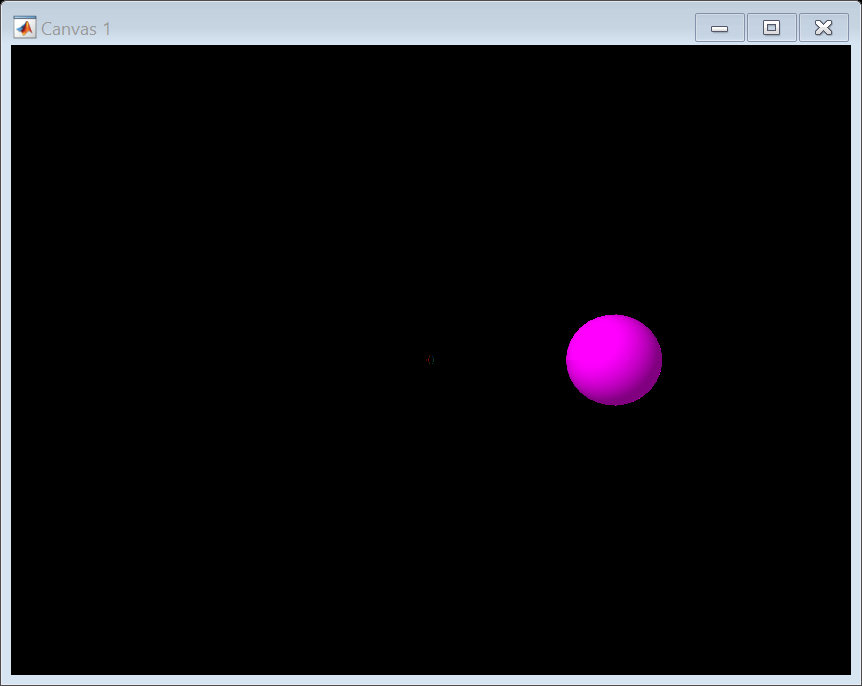

    rate(1/dt);
    t = t + dt;
end

Experiment with different values of periods/second in the argument to `rate()` and note how the animation rate (loops/second) and the particle's period (periods/simsecond) interact. Keep this relationship in mind as you use the `rate()` function of PHYSVIS to create animations.

© Copyright 2017 The MathWorks, Inc.